# Ballbot robust stability analysis and validation script

**Contents:**

- Nonlinear model synthesis with distrubances

- Parametric linearisation 

- Parametric uncertainty introduction

- optimisation based worst case search

- Disturbance rejection and noise attenutation

- H-infinity controller synthesis

- based on linear systems 

- based on worst case system

- Comparison of behavior with nonlinear model

clear all
mkdir('generated')
addpath('./generated')
addpath('./visualisation')
addpath('./optimisation')

## Model physical parameters definition

Introducing the physical parameters of the system

global rK_n rW_n  rA_n  l_n  mAW_n mK_n  A_ThetaAWx_n  A_ThetaAWy_n  A_ThetaAWz_n  ThetaKi_n  ThetaWi_n;

% Uncertain parameters
rK_n = 0.120; % radius of the ball
rW_n = 0.05; % radius of omni wheel=5cm
rA_n = 0.126; % radius of the body  
l_n = 0.22634; % distance between centre of ball and centre of gravity of the body 
mAW_n = 6.71; % mass of the body and omni wheel  
mK_n = 0.625; % mass of the basket ball  
A_ThetaAWx_n = 1.41271413; % Inertia of the body and Omni wheels in the body reference frame A  
A_ThetaAWy_n = 1.41271311;
A_ThetaAWz_n = 0.05359646;
ThetaKi_n = 0.003606375;
ThetaWi_n = 0.01504; 

% Angle of motors
alpha = 47*pi/180;
beta1 = 0;
beta2 = 2/3*pi;
beta3 = 4/3*pi;

% vector of nominal parameters
params_n = [rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n];

## Derivation script of the nonlinear model

Modeling ot the nonlinear system - extended matlab version of the script FInal.nb made in Mathematica

- Parametric nonlinear model creation

- Linearization around 0

- Creation of simulation functions for further analyisis - linear and nonlinear

Execution can take 5-10 minutes

model_generation;

## Linear nominal model sysnthesys

Creation of linear transfer funciton based on linearised matrices of the Ballbot and the nominal parameters

Additionally the LQR controller is provided (based on the LQR controller in the report) as a default controller to be compared in further analysis.


% A matrix
tic
A_n= fA(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('A matrix :  %f sec\n',toc);
% B matrix
tic
B_n= fB(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('B matrix :  %f sec\n',toc);
% B_w matrix
tic
B_w= fW(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('B_w matrix :  %f sec\n',toc);

% state space model from matrices
G_n = ss(A_n, B_n, eye(10), zeros(10,3));


LQR controller synthesis


% LQR controller design
Q = diag([100 50 100 50 40 20 20 10 20 10]);
R = diag([100 100 100]);
K_lqr = lqr(G_n,Q,R);

## Linear and nonlinear model initial condition response comparison

Finally, simple graph of initial condition response for linear and nonlinear system with nominal parameters to see how well does the lienarized system corespond with the nonlinear

X0 = [pi/20 0 pi/20 0 pi/10 0 0 0 0 0]';
T_max = 4; %s
initialplot_compare_nlin(@nlin_model_n,G_n,K_lqr,X0,T_max,1,2)
drawnow

## Introducing the uncertainties

The uncertainties are introduced into the physiscal parameters of the system. The idea is that for the variables you cannot measure you should have some uncertainty about their values. 

The uncertainties are set as the percentage.For example if l_var is 20, that means that your height of center of mass can be +-20% different than your nominal value.

% Uncertain variation of the parameters
A_ThetaAWx_var = 15; % percent
l_var = 10; % percent
A_ThetaAWz_var = 15;% percent
ThetaKi_var = 15;% percent
A_ThetaAWy_var = 15; % percent
ThetaWi_var = 15;% percent

% sample the uncertain models
visualize_uncertainty_samples

## Find the worst case system based on parameter uncertainties

To be able to find the worst case parameters we define the optimisation problem based on disk margin. 

Basically we are changing the parameter values and searching to the minimum of the stability margin (diskmargin)

The minimal margin corresponds to the worst case parameters

wcu = find_wcu_optimisation(l_var, ThetaWi_var, ThetaKi_var, A_ThetaAWx_var, A_ThetaAWy_var, A_ThetaAWz_var, K_lqr)
% variable wcu contains 
% wcu.l,ThetaKi,... - the worst case parameters 
% wcu.min_margin    - worst case margin
% wcu.max_gain      - worst case gain
% wcu.G             - linear state space model of the worst case transfer function


## Nominal and worst case linear model comparison

#### Margin comparison

% nominal parameters
MMIO_n = diskmargin(G_n,K_lqr)
%worst case parameters
MMIO_wc = diskmargin(wcu.G,K_lqr)

#### Initial condition response

% initialplot
X0 = [pi/20 0 pi/20 0 pi/10 0 0 0 0 0]';
T_sim = 3; %sec=
initialplt(feedback(wcu.G,K_lqr),'b',X0,T_sim,110); 
initialplt(feedback(G_n,K_lqr),'r',X0,T_sim,110);
legend('worst case','nominal')
sgtitle('Closed loop (LQR) - Inirtial condition response comparison nominal and worst case')

#### Singular value plota

figure(111);
sigma(feedback(wcu.G,K_lqr),'b');
hold on;
sigma(feedback(G_n,K_lqr),'r');
legend('worst case','nominal')
grid on;
sgtitle('Closed loop (LQR) - Singular value plot comparison nominal and worst case')

## Validate worst case performance with the nonlinear model

Interesting is to see if nonlinear system is still stable for worst case parameters and LQR controller calculated for the nominal parameters.

% generate the worst  case parameters nonlinear model ans save it to  nlin_model_wcu function
model_generation_worst_case;

% Simulate and compare worst case linear and nonliner
initialplot_compare_nlin(@nlin_model_wcu,wcu.G,K_lqr,X0,T_sim,120,121)
figure(120);
sgtitle('Linearized and nonlinear WC system with LQR controller - states')
figure(121);
sgtitle('Linearized and nonlinear WC system with LQR controller - control signals')
drawnow

# Distrubance rejection and noise attenuation

#### **Ballbot has two type of disturbance **

 - ***force acting on the body - hunam interaction ****(w)*

 - ***measurement noise *** (*n*)

   > acceletometer and gyro

   > influences thetax, d_thetax, thetay, d_thetay  

#### ** Ballbot system**

 dx = Ax + [B_n B_w B_u]*[w n u]'

 y = Cx + [D_n D_w D_u]*[w n u]'

 u = K*x

% definining the standardized testing input for distrubance rejection
t_d = linspace(0,20,2000);
N_d = length(t_d);
n = randn(4,N_d);
n = n/max(n(:));
wx = [zeros(1,0.2*N_d), ones(1,0.1*N_d), zeros(1,0.7*N_d)];
wy = [zeros(1,0.7*N_d), -ones(1,0.1*N_d) zeros(1,0.2*N_d)];
dist = [n; wx; wy];

figure(200);
state_var_names = {'\vartheta_x', '\vartheta_x`','\vartheta_y', '\vartheta_y`'};
for i = 1:4
    subplot(6,1,i);
    plot(t_d,dist(i,:),'LineWidth',1.5);
    hold on
    title(strcat(state_var_names{i},'(n',num2str(i),')'))
    if mod(i,2)
        ylabel('rad')
    else
        ylabel('rad/s')
    end
end
w_names={'T_x','T_y'};
for i = 1:2
    subplot(6,1,4+i);
    plot(t_d,dist(4+i,:),'LineWidth',1.5);
    hold on
    title(strcat(w_names{i},'(w',num2str(i),')'))
    ylabel('Nm')
end
sgtitle('Testing input signal - measurement noise and disturbance force on the body')

## Creating the factorial representaion

%% disturbance matrix
B_w = fW(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
% noise matrix
B_n = zeros(10,4);
% measurement noise variance 1 degree 
D_n = 0.5/180*pi*eye(10,4); 
% input D matrix
D_u = zeros(10,5);
C_z = [G_n.c; zeros(3,10)];
D_z = [D_n  D_u ; [zeros(3,6) 5*eye(3)]];
% model for h-infinity synthesis containing z output
Pz = ss(G_n.a, [B_n B_w G_n.b], [C_z; G_n.c], [ D_z; [D_n D_u] ]);
D_y = [D_n  D_u ; [zeros(3,6) eye(3)]];
% model for simulation using y as output
P = ss(G_n.a, [B_n B_w G_n.b], [C_z; G_n.c], [ D_y; [D_n D_u] ]);

% worst case model
% disturbance matrix
B_w_wcu = fW(rK_n, rW_n, rA_n, wcu.l, mAW_n, mK_n, wcu.A_ThetaAWx, wcu.A_ThetaAWy, wcu.A_ThetaAWz, wcu.ThetaKi, wcu.ThetaWi);
% model for h-infinity synthesis containing z output
Pz_wc = ss(wcu.G.a, [B_n B_w_wcu wcu.G.b], [C_z; wcu.G.c], [ D_z; [D_n D_u]]);
% model for simulation using y as output
P_wc = ss(wcu.G.a, [B_n B_w_wcu wcu.G.b], [C_z; wcu.G.c], [ D_y; [D_n D_u]]);

## Initial LQR disturbance rejection

Compariosn of linear and nonliner performcane using nominal and worst case parameters

% complarison linear nonlinear disturbance rejection
nlsim(@nlin_model_n,-K_lqr,dist,t_d,P,201,202);
figure(201)
sgtitle('LQR linear vs nonlinear model with nominal parameters - states')
figure(202)
sgtitle('LQR linear vs nonlinear model with nominal parameters - control signals')
% complarison linear nonlinear disturbance rejection
nlsim(@nlin_model_wcu,-K_lqr,dist,t_d,P_wc,203,204);
figure(203)
sgtitle('LQR linear vs nonlinear model with worst case parameters - states')
figure(204)
sgtitle('LQR linear vs nonlinear model with worst case parameters - control signals')


### Singular value plot for disturbance rejection fonominal and worst case model

% plot singular values of distrurbance rejection loop
figure(301)
sigma(lft(P,-K_lqr),'r',lft(P_wc,-K_lqr),'b',(0.1:0.01:100));
legend('nominal','worst case');
grid on
title('Singular values plot for distrubance rejection closed loop with LQR')

## H-infinity controller design

Fixed structure - gain U=K*x;

%% H-infinity controller design fixed
% hinf fixed structure - gain
K_tun = realp('K_t',K_lqr);   
K_tun.Minimum = -100*ones(3,10); 
K_tun.Maximum = 100*ones(3,10);
opts = hinfstructOptions('TargetGain',0,'MaxIter',500,'RandomStart',5,'MaxFrequency',20);
[C,gamma,info] = hinfstruct(Pz_wc,-K_tun,opts);

Final: Peak gain = 7.45, Iterations = 378
Final: Peak gain = 7.33, Iterations = 686
Final: Peak gain = 7.23, Iterations = 613
Final: Peak gain = 7.2, Iterations = 503
Final: Peak gain = 7.32, Iterations = 669
Final: Peak gain = 9.34, Iterations = 681


K_hinf = C.Blocks.K_t.Value

K_hinf =    98.7148   28.6617  -70.5568   15.9746  -45.7233   -2.8785    3.5859    1.7355   -4.2880    1.1114
  -23.4766  -10.3519   48.6298   83.6782  -57.4469    0.9153    2.9626   -0.7716   -3.9391    4.4414
  -53.8635  -15.7650  -99.9197  -54.1078    4.5926   -4.6286   -0.8235   -0.6983   -0.6889   -2.6081


## **Comparison of H-infinity and LQR **

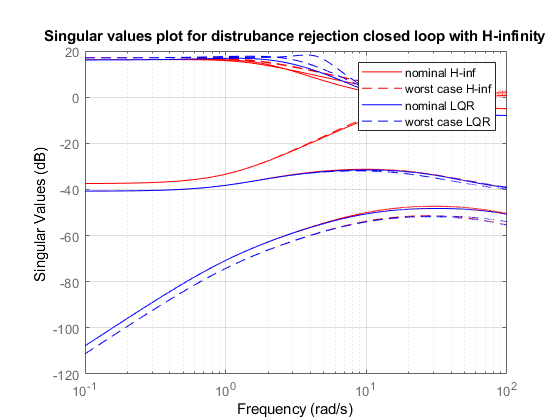

% plot singular values of distrurbance rejection loop
figure(302)
sigma(lft(P,-K_hinf),'r',lft(P_wc,-K_hinf),'--r',lft(P,-K_lqr),'b',lft(P_wc,-K_lqr),'--b',(0.1:0.01:100));
legend('nominal H-inf','worst case H-inf','nominal LQR','worst case LQR');
grid on
title('Singular values plot for distrubance rejection closed loop with H-infinity')

## Complarison H-infinity and LQR linear models

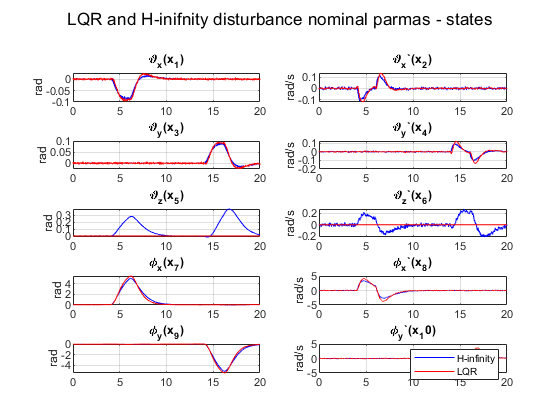

linsim(lft(P,-K_hinf),'b',dist,t_d,303,304);
linsim(lft(P,-K_lqr),'r',dist,t_d,303,304);
figure(303)
sgtitle('LQR and H-inifnity disturbance nominal parmas - states')
legend('H-infinity','LQR')

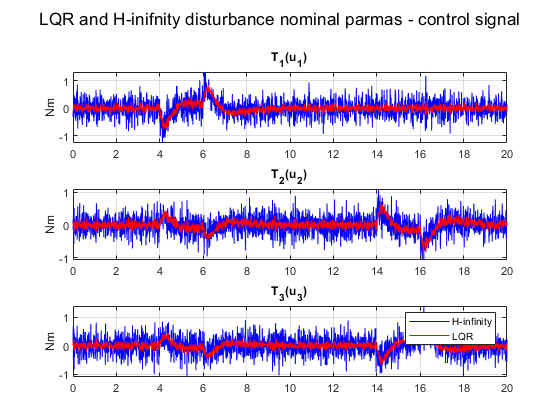

figure(304)
sgtitle('LQR and H-inifnity disturbance nominal parmas - control signal')
legend('H-infinity','LQR')

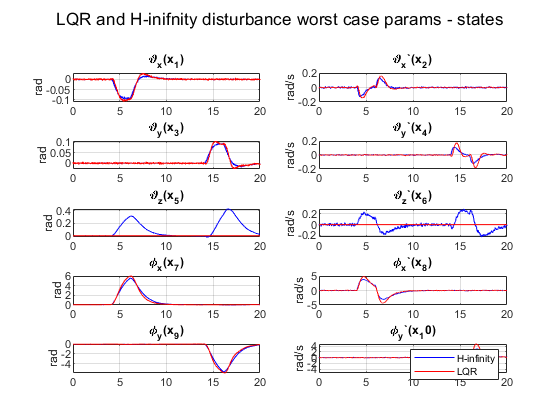

linsim(lft(P_wc,-K_hinf),'b',dist,t_d,305,306);
linsim(lft(P_wc,-K_lqr),'r',dist,t_d,305,306);
figure(305)
sgtitle('LQR and H-inifnity disturbance worst case params - states')
legend('H-infinity','LQR')

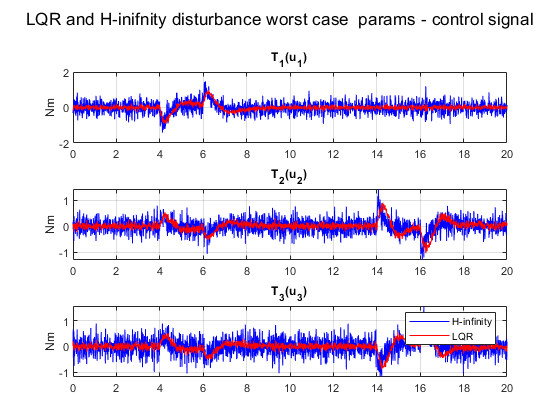

figure(306)
sgtitle('LQR and H-inifnity disturbance worst case  params - control signal')
legend('H-infinity','LQR')

### Bode diagram of comparison 

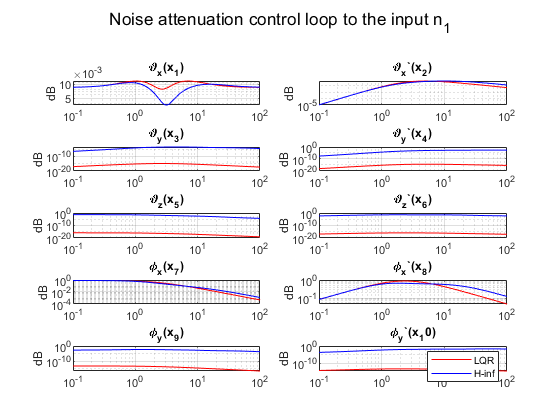

H_lqr = lft(P,-K_lqr);
H_hinf = lft(P,-K_hinf);
bodemg(H_lqr(1:10,1),'r',311);
hold on
bodemg(H_hinf(1:10,1),'b',311);
legend('LQR', 'H-inf')
sgtitle('Noise attenuation control loop to the input n_1');

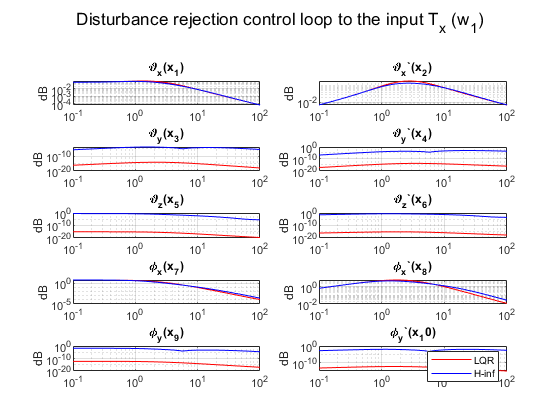


bodemg(H_lqr(1:10,5),'r',312);
hold on
bodemg(H_hinf(1:10,5),'b',312);
legend('LQR', 'H-inf')
sgtitle('Disturbance rejection control loop to the input T_x (w_1)');

## Complarison H-infinity and nonlinear model

nlsim(@nlin_model_n,-K_hinf,dist,t_d,P_wc,307,308);

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 50.996019 seconds.


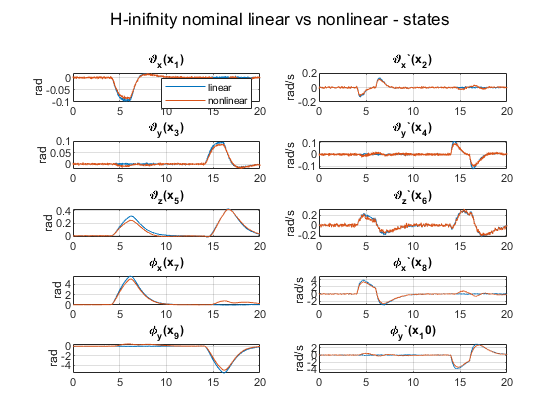

figure(307);
sgtitle('H-inifnity nominal linear vs nonlinear - states')

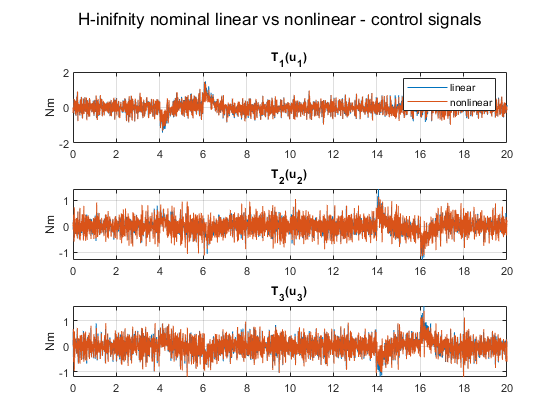

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 52.005536 seconds.


figure(308)
sgtitle('H-inifnity nominal linear vs nonlinear - control signals')
nlsim(@nlin_model_wcu,-K_hinf,dist,t_d,P,309,310);

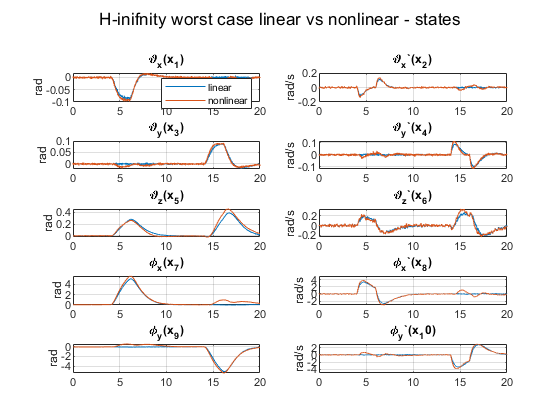

figure(309)
sgtitle('H-inifnity worst case linear vs nonlinear - states')

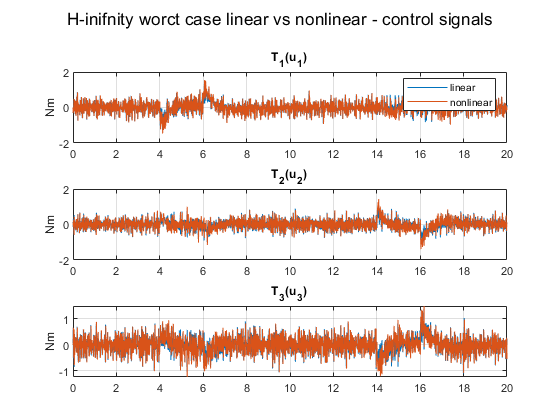

figure(310)
sgtitle('H-inifnity worct case linear vs nonlinear - control signals')

## State space H-infinity controller 

State space controller

%% H-infinity controller 
ns = 3;
A_tun = realp('A_t',rand(ns,ns));   
B_tun = realp('B_t',rand(ns,10));   
C_tun = realp('C_t',rand(3,ns));   
D_tun = realp('D_t',rand(3,10));   
opts = hinfstructOptions('TargetGain',0,'MaxIter',500,'RandomStart',5,'MaxFrequency',20);
K_tun = ss(A_tun,B_tun,C_tun,D_tun);
[C,gamma,info] = hinfstruct(Pz_wc,K_tun,opts);

Final: Peak gain = 7.09, Iterations = 824
Final: Peak gain = 7.59, Iterations = 646
Final: Peak gain = 7.08, Iterations = 597
Final: Peak gain = 7.22, Iterations = 559
Final: Peak gain = 7.16, Iterations = 743
Final: Peak gain = 7.15, Iterations = 650


K_hinf_ss = ss(C.Blocks.A_t.Value,C.Blocks.B_t.Value,C.Blocks.C_t.Value,C.Blocks.D_t.Value)


K_hinf_ss =
 
  A = 
            x1       x2       x3
   x1   0.4412   -4.209   0.7456
   x2    8.302   -30.14  -0.2614
   x3   -32.67    24.91   -7.031
 
  B = 
           u1      u2      u3      u4      u5      u6      u7
   x1  -44.81  -29.35  -45.73   8.114   14.96   2.344   13.22
   x2  -11.78  -49.81   15.69  -79.68   61.24   2.501   46.02
   x3    22.1   77.09   49.67   82.58   26.85  -16.88  -7.771
 
           u8      u9     u10
   x1  0.9711  -5.109  0.8327
   x2  -3.869  -23.43  -8.206
   x3  0.9775   15.75  -3.086
 
  C = 
           x1      x2      x3
   y1   3.974  -8.272   0.352
   y2  -5.363   3.732  -1.758
   y3  -3.345   3.587  0.5774
 
  D = 
            u1       u2       u3       u4       u5       u6
   y1   -38.47   -33.06     7.76   0.9153    27.07   0.9527
   y2    29.09    22.36   -45.27   -78.58    26.45     7.01
   y3    29.26    22.08   -3.408    70.24    3.785  -0.4199
 
            u7       u8       u9      u10
   y1    11.66   -2.873   -6.499  -0.7479
   

## Comparison LQR and H-inifnity state space

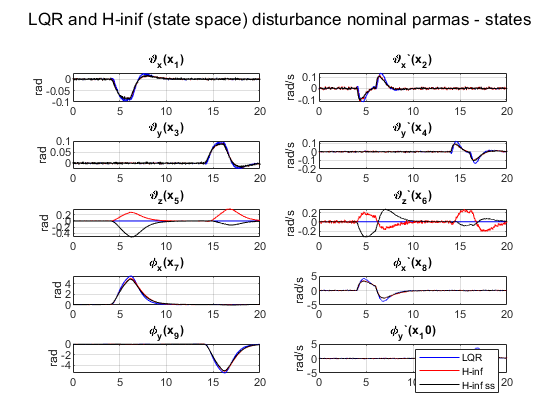

linsim(lft(P,-K_lqr),'b',dist,t_d,404,405);
linsim(lft(P,-K_hinf),'r',dist,t_d,404,405);
linsim(lft(P,K_hinf_ss),'k',dist,t_d,404,405);
figure(404)
sgtitle('LQR and H-inif (state space) disturbance nominal parmas - states')
legend('LQR','H-inf','H-inf ss')

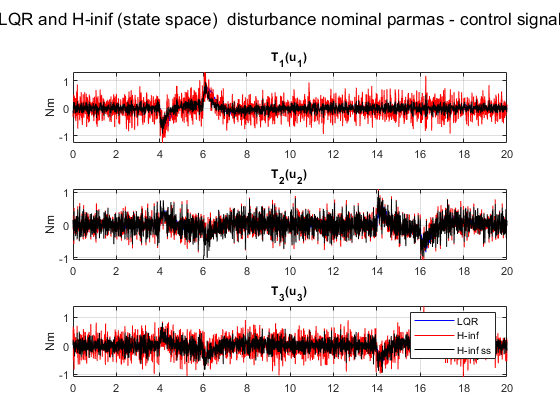

figure(405)
sgtitle('LQR and H-inif (state space)  disturbance nominal parmas - control signal')
legend('LQR','H-inf','H-inf ss')

## Complarison H-infinity and nonlinear model

nlsim(@nlin_model_n,K_hinf_ss,dist,t_d,P_wc,307,308);

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 39.202894 seconds.


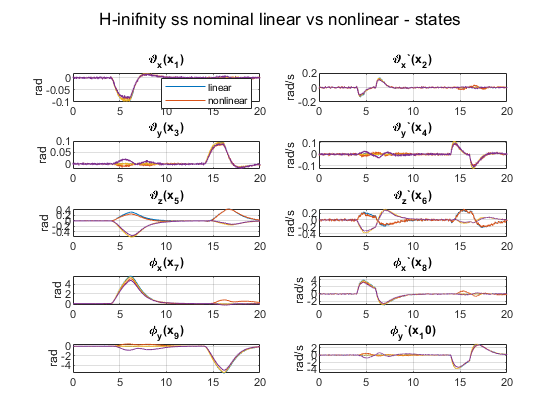

figure(307);
sgtitle('H-inifnity ss nominal linear vs nonlinear - states')

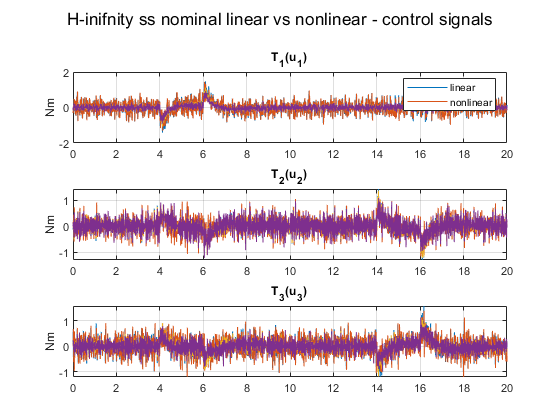

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 37.667418 seconds.


figure(308)
sgtitle('H-inifnity ss nominal linear vs nonlinear - control signals')
nlsim(@nlin_model_wcu,K_hinf_ss,dist,t_d,P,309,310);

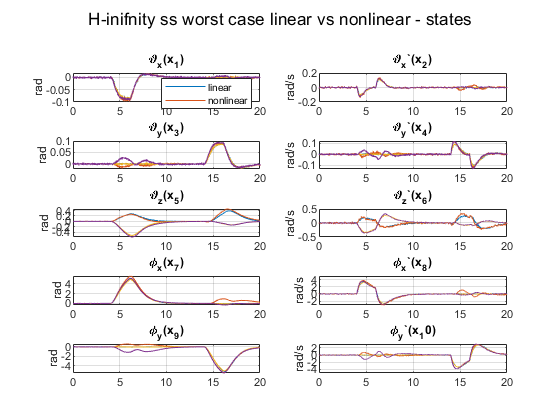

figure(309)
sgtitle('H-inifnity ss worst case linear vs nonlinear - states')

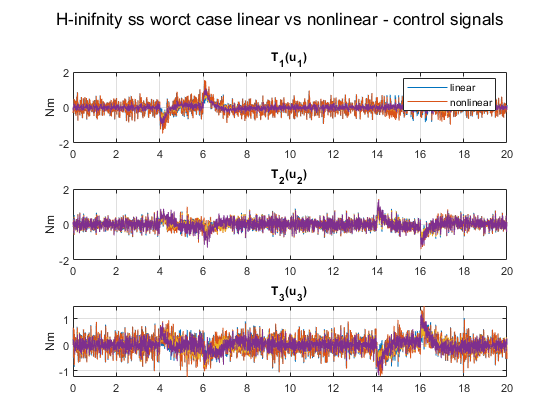

figure(310)
sgtitle('H-inifnity ss worct case linear vs nonlinear - control signals')

## Bode diagram of LQR, H-infinity gain and H-infinity state space

We can see that state space H-infinity controller has lowest gain for almost all the transfrer functions on the plot making it the most robustly stable one.

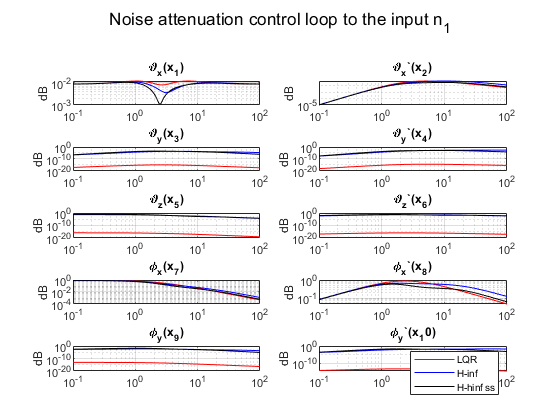

figure(406)
H_hinf_ss = lft(P,K_hinf_ss);
bodemg(H_lqr(1:10,1),'r',406);
hold on
bodemg(H_hinf(1:10,1),'b',406);
bodemg(H_hinf_ss(1:10,1),'k',406);
legend('LQR', 'H-inf', 'H-hinf ss')
sgtitle('Noise attenuation control loop to the input n_1');

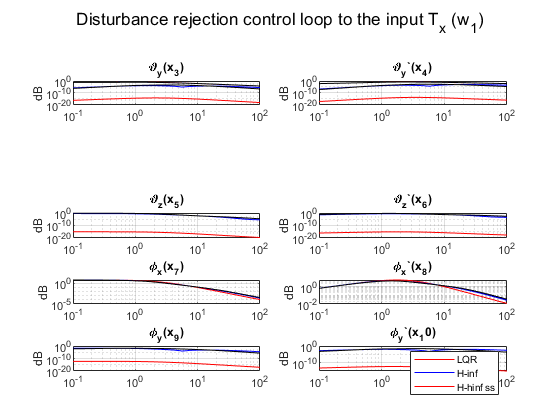

bodemg(H_lqr(1:10,5),'r',312);
hold on
bodemg(H_hinf(1:10,5),'b',312);
bodemg(H_hinf_ss(1:10,5),'k',312);
legend('LQR', 'H-inf','H-hinf ss')
sgtitle('Disturbance rejection control loop to the input T_x (w_1)');

## H-infintiy norms for nominal and worst case parameter linear model comparison of LQR, fixed H-inifnity and state space H-Infinity controller

hinfnorm(lft(P,-K_lqr))

ans = 6.9632

hinfnorm(lft(P,-K_hinf))

ans = 6.5901

hinfnorm(lft(P,K_hinf_ss))

ans = 6.4895

hinfnorm(lft(P_wc,-K_lqr))

ans = 8.1786

hinfnorm(lft(P_wc,-K_hinf))

ans = 7.1935

hinfnorm(lft(P_wc,K_hinf_ss))

ans = 7.0820

## Closed loop singular value plot comparison

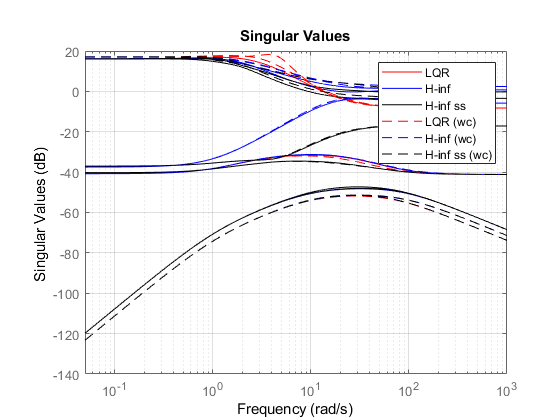

% plot singular values of distrurbance rejection loop
figure(407)
sigma(lft(P,-K_lqr),'r',lft(P,-K_hinf),'b',lft(P,-K_hinf_ss),'k',lft(P_wc,-K_lqr),'--r',lft(P_wc,-K_hinf),'--b',lft(P_wc,-K_hinf_ss),'--k',(0.05:0.01:1000));
legend('LQR','H-inf','H-inf ss','LQR (wc)','H-inf (wc)','H-inf ss (wc)');
grid on;